clear all

%% DEFINE THE PLANT INITIAL CONDITIONS

% Initial motor angle [radians]
theta_m_init = deg2rad(45);
% Initial link angle [radians]
theta_l_init = deg2rad(45);
% Initial motor velocity [radians/second]
thetadot_m_init = deg2rad(0);
% Initial link velocity [radians/second]
thetadot_l_init = deg2rad(0);
% Initial motor current [Amps]
Ia_init = 0;

% Initial conditions stacked as a 5x1 vector
init = [theta_m_init; theta_l_init; thetadot_m_init; thetadot_l_init; Ia_init];

%% DEFINE THE SENSOR PARAMETERS

% FOR VISION:
% > The frames per second [fps]
% > Allowed values: 25, 50, 100
vision_fps = 25;

% FOR ABSOLUTE ENCODER
% > Number of counts per revolution
absolute_encoder_counts_per_revolution = 128;

% FOR POTENTIOMETER
% > Percentage linearity [percent]
potentiometer_linearity_percent = 20;

% FOR TACHOMETER
% > Number of counts per revolution
tachometer_counts_per_revolution = 2048;
% > Frequency of the velocity estimates
% > Allowed values: 10, 25, 50, 100
tachometer_output_frequency = 50;

% FOR GYROSCOPE
% > Variance of the noise that drives the drift process [rad/s^2]
gyro_sigma_drift = deg2rad(5);

Jl =0.001;
m =0.1;
g =9.81;
l =0.1;
Ks =1.75;

% Motor 1

Km =0.5369;
Jm =0.0021;
La =0.18*(10^(-3));
Ra = 2.6;

% % Motor 2
% 
% Km =0.027;
% Jm =7.5*(10^-6);
% La =1.3*(10^(-3));
% Ra = 2;
% 
% %Motor 3
% 
% Km =0.0229;
% Jm =54*(10^-6);
% La =1.3*(10^(-3));
% Ra = 8;

## State space model and transfer function

A=[0 0 1 0 0;0 0 0 1 0;(-Ks/Jm) (Ks/Jm) 0 0 (Km/Jm);(Ks/Jl) (-Ks/Jl-(m*g*l)/(Jl)) 0 0 0;0 0 -Km/La 0 -Ra/La];
det(A)

ans = -1.1808e+09

B=[0;0;0;0;1/La];

C=[0 1 0 0 0];

D=0;

[num,den]=ss2tf(A,B,C,D);

G=tf(num,den);

zpk(G) 

ans =
 
                        2.4856e+09
  -------------------------------------------------------
  (s+1.439e04) (s+42.74) (s+0.8577) (s^2 + 9.392s + 2238)
 
Continuous-time zero/pole/gain model.
Model Properties


## Designing controller by loop shaping

s=tf('s');

Mp=10; %%how much overshoot as a percentage

zeta_min=-(log(Mp/100))/(sqrt(pi^2+(log(Mp/100))^2)); %%minimum value zeta can take

zeta=0.8; %actual zeta value we will use

wn_min=(1/(2*zeta))*log(100/(2*(sqrt(1-zeta^2))))

wn_min = 2.7643


wn=wn_min;

Mf_min=atand(2*zeta/(sqrt(sqrt(1+4*(zeta)^4)-2*zeta^2))) %%minimum phase margin we must try achieve

Mf_min = 69.8600


Mf=75*(pi/180); %actual phase margin im designing for

wc_min=wn*sqrt(sqrt(1+(4*(zeta^4)))-2*(zeta)^2) %%must be greater than this value

wc_min = 1.6220


wc=9; %%actual value we will use

tz2=10/wc;

tp=1/(10*wc);

%%%finding tz1 by rearranging eq 19 from Workshop 1
q=wc*1i; %(s)

phaseGC=angle(q*tz2+1)-angle(q)-angle(q*tp+1)-angle(q+1.439e04)-angle(q+43.41)-angle(q+0.8516)-angle((q^2)+8.726*q+1966);

tz1=(tan(Mf-pi-phaseGC))/wc

tz1 = 0.0100


%%%finding K by rearranging eq 20 from Workshop 1
syms t;

numtf=2.2016e9; %numerator of tf with symbolic variable t replacing s

dentf=(t+1.439e04)*(t+43.41)*(t+0.8516)*(t^2+8.726*t+1966); %denominator of tf with symbolic variable t replacing s

G2=numtf/dentf; %transfer function with symbolic variable t replacing s

G3=subs(G2,t,wc*1i);%replace t with wc*j

magG=double((abs(G3))); %magnitude of tf evaluated at wc

K_gain=double((wc*abs(tp*wc*1i+1))/(abs(tz1*wc*1i+1)*abs(tz2*wc*1i+1)*magG)) %%lower bound

K_gain = 4.4300


C_pid=K_gain*(((tz1*s)+1)*((tz2*s)+1))/((s)*((tp*s)+1))

C_pid =
 
  0.04929 s^2 + 4.967 s + 4.43
  ----------------------------
        0.01111 s^2 + s
 
Continuous-time transfer function.
Model Properties


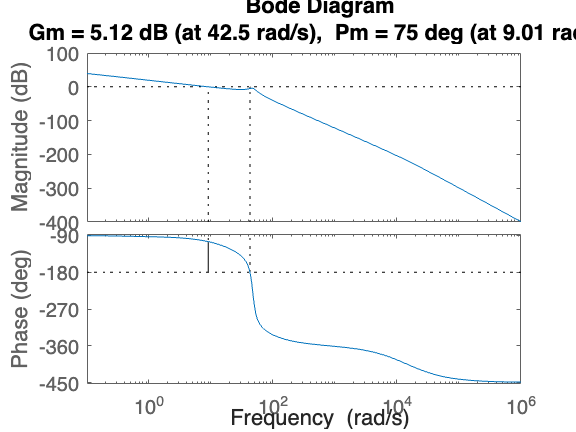


margin(G*C_pid)

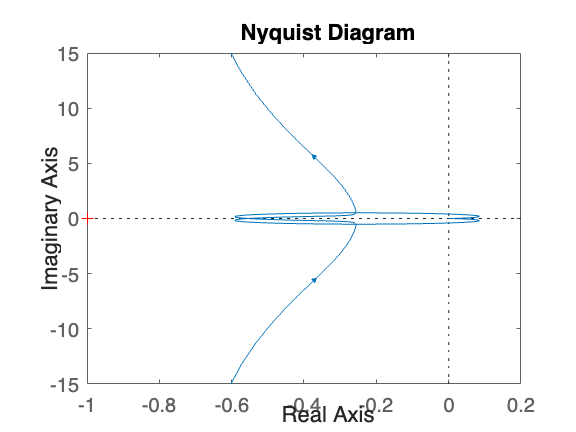


nyquist(G*C_pid)


zpk(G*C_pid);

To=(G*C_pid)/(1+(G*C_pid))

To =
 
                                         1.361e06 s^9 + 1.992e10 s^8 + 4.806e12 s^7 + 4.316e14 s^6 + 2.168e16 s^5 + 8.59e17 s^4 + 1.831e19 s^3 + 3.024e19 s^2 + 1.3e19 s
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  0.0001235 s^14 + 3.589 s^13 + 2.659e04 s^12 + 7.438e06 s^11 + 9.14e08 s^10 + 7.247e10 s^9 + 4.405e12 s^8 + 2.005e14 s^7 + 6.846e15 s^6 + 1.793e17 s^5 + 3.011e18 s^4 + 2.166e19 s^3 + 3.164e19 s^2 + 1.3e19 s
 
Continuous-time transfer function.



zpk(To) %%closed loop TF

ans =
 
                    1.1028e10 s (s+1.439e04) (s+99.85) (s+90) (s+42.74) (s+0.9) (s+0.8577) (s^2 + 9.392s + 2238)
  ---------------------------------------------------------------------------------------------------------------------------------
  s (s+1.439e04)^2 (s+90.18) (s+90) (s+42.74) (s+34.18) (s+12.51) (s+0.9047) (s+0.8577) (s^2 + 5.207s + 1974) (s^2 + 9.392s + 2238)
 
Continuous-time zero/pole/gain model.


## Discretising controller with sampling time Ts

Freq=50;

Ts=1/Freq;

Cz_zoh=c2d(C_pid,Ts,'zoh');

Cz_euler=c2d_euler(C_pid,Ts,'forward');

## Plotting

% hold off
% plot(out.theta)
% hold off

% t=linspace(0,10);
% theta_ref=(30/pi)*asind(sind(t*pi/2+pi/2))+30;
% plot(t,theta_ref,'b--');
% hold on
% plot(out.theta,'b-')
% grid on
% hold on
% plot(theta1,'b:')
% xlabel('Time [s]')
% ylabel('angular position [deg]')
% legend('theta ref','theta sim continuous','theta sim discrete')
% hold off